# AAE 36401 Lab 3 Section 3

addpath('simfiles')
addpath('ourfiles')
addpath('exp2_2')
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);
setup_lab_ip01_2_sip

K = lqr(a,b,diag([25 25 3 3 90]),.1)

K =   -42.4888   84.3299  -33.5350   13.3860   30.0000


poleslqr = eig(a-b*K)

poleslqr =  -40.8724 + 0.0000i
  -3.3671 + 1.7481i
  -3.3671 - 1.7481i
  -1.5493 + 0.9965i
  -1.5493 - 0.9965i


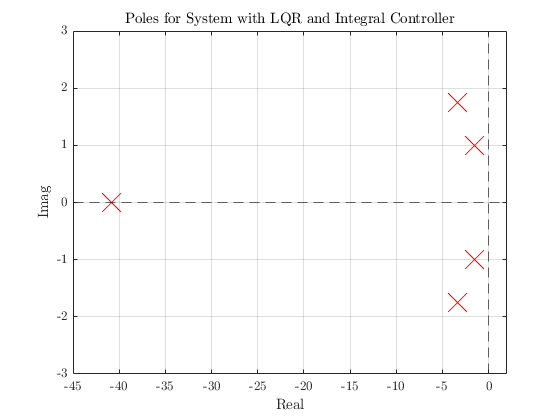


plot(real(poleslqr),imag(poleslqr),'rx','markersize',20)
grid on, xline(0,'--'), yline(0,'--'), xlim([-45,2]), ylim([-3 3])
title('Poles for System with LQR and Integral Controller')
xlabel('Real'), ylabel('Imag')

data = load('3');
t = data.x_c_3_2.time;
th = data.Theta_3_2.signals.values;
x = data.x_c_3_2.signals.values;

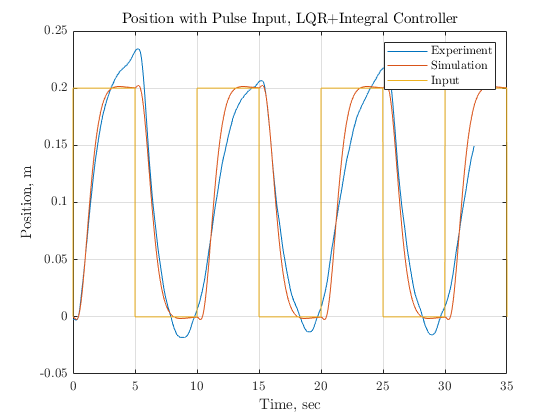

sim('aae364pinv2')
tsim = pos.time; possim = pos.data; thsim = theta.data; inputsim = input.data;
plot(t-20.4580,x)
hold on
plot(tsim-5,possim+.1)
plot(tsim-5,inputsim+.1)
xlim([0,35])
xlabel('Time, sec'), ylabel('Position, m')
title('Position with Pulse Input, LQR+Integral Controller')
legend('Experiment','Simulation','Input')
grid on
hold off

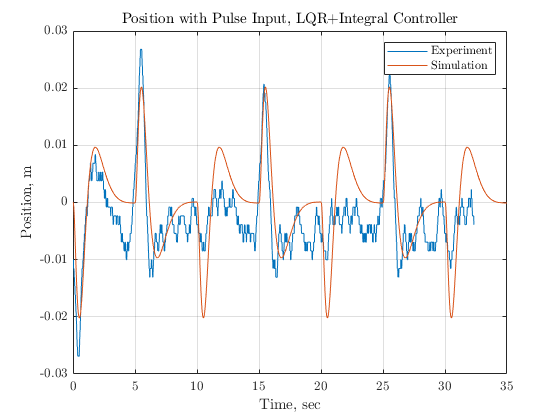

plot(t-20.4580,th+.005)
hold on
plot(tsim-5,thsim)
xlim([0,35])
grid on
xlabel('Time, sec'), ylabel('Position, m')
title('Position with Pulse Input, LQR+Integral Controller')
legend('Experiment','Simulation')
hold off